clear;
A = 0.32345;
B = -0.78743;
C = 0.56532;

sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=8; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word
A_fix = fi(A, sign, word, prec_f)

A_fix =     0.3242

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

B_fix = fi(B, sign, word, prec_f)

B_fix =    -0.7891

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

C_fix = fi(C, sign, word, prec_f)

C_fix =     0.5664

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8


bin(A_fix)

ans = '0001010011'

o=double(A_fix)

o = 0.3242

Y_fix = (A_fix + B_fix) * C_fix

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

Y = (A + B) * C

Y = -0.2623

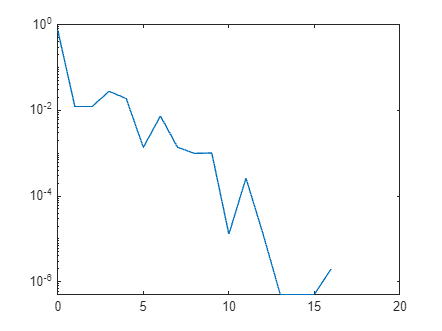

err_v = [];
for i = 0:1:16
    prec_f = i;
    word = 1 + prec_i + prec_f; % whole word
    A_fix = fi(A, sign, word, prec_f);
    B_fix = fi(B, sign, word, prec_f);
    C_fix = fi(C, sign, word, prec_f);
    Y_fix = (A_fix + B_fix) * C_fix;

    err(i+1) = abs(Y - double(Y_fix));
end %for

semilogy(0:1:16, err)